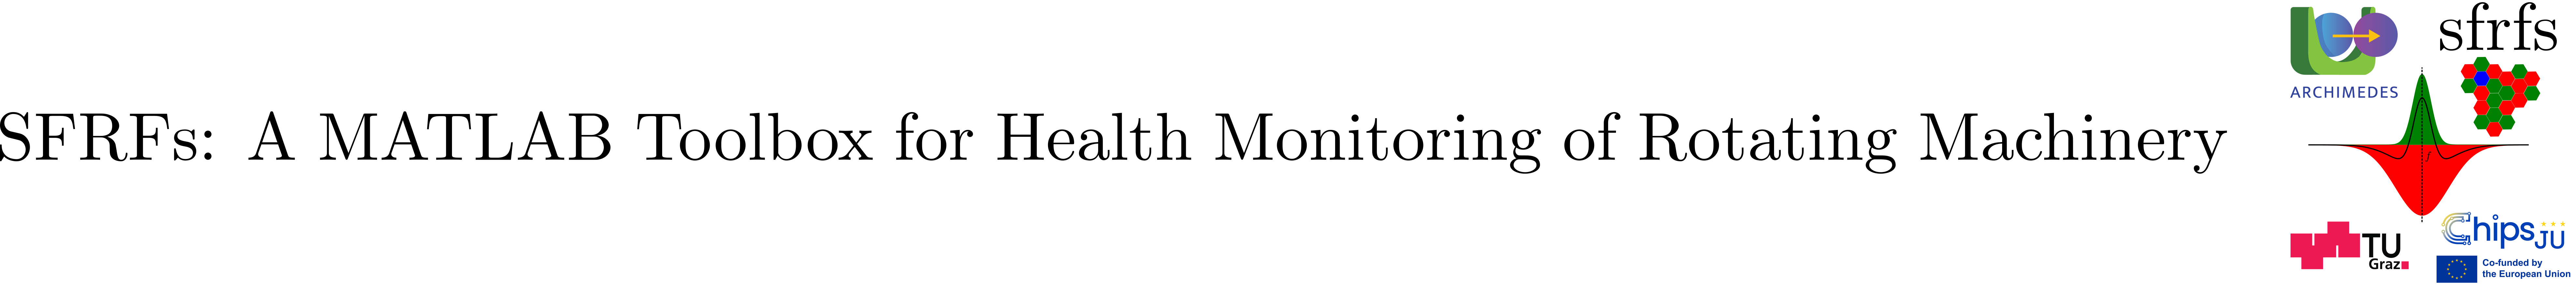

# FaultConditionTableMetaSchema 

## Summary

`FaultConditionTableMetaSchema` provides constant column names for tables storing fault-specific records evaluated at concrete operating conditions.

## Description

A fault-condition table is uniquely selectable by the key:

`(FaultGroup, Speed, Load)`.

This schema centralizes the corresponding column-name constants (plus a human-readable description), avoiding hard-coded string literals across the toolbox.

### Defined columns

### Notes

- This schema defines the **minimal contract** for all fault-condition indexed tables in the toolbox.

- The key `(FaultGroup, Speed, Loa`d) ensures uniqueness and supports consistent row selection across computational stages.

- Derived schemas may extend this base without redefining these columns.

### See also

[`tables.FaultBandsTableSchema`](matlab:open('./FaultBandsTableSchema.mlx'))`, `[`tables.GainFunctionsTableSchema`](matlab:open('./GainFunctionsTableSchema.mlx'))`, `[`OperatingConditions`](matlab:open('./OperatingConditions.mlx'))`, `[`FaultFrequencyBands`](matlab:open('./FaultFrequencyBands.mlx'))`, `[`ReceptiveFieldGainFunctions`](matlab:open('./ReceptiveFieldGainFunctions.mlx'))

## Example

% Example: set and get columns in a fault-condition table using schema keys

import tables.FaultConditionTableMetaSchema

ft = SFRFsParametersRollingBearings.OUTER_RACE_FAULT_TYPE_NAME;

fg = BearingFrequencyBands.faultTypeGroups(ft);
ds = BearingFrequencyBands.faultTypeDescriptions(ft);

% Set columns
T = table();
T.(FaultConditionTableMetaSchema.FAULTGROUP) = fg;
T.(FaultConditionTableMetaSchema.SPEED) = 35;
T.(FaultConditionTableMetaSchema.LOAD) = 12;
T.(FaultConditionTableMetaSchema.DESCRIPTION) = ds;

% Get columns
disp("FaultCondition = (" + T.(FaultConditionTableMetaSchema.FAULTGROUP) + ", " + ...
    T.(FaultConditionTableMetaSchema.SPEED) + " Hz, " + ...
    T.(FaultConditionTableMetaSchema.LOAD) + " kN) : " + ...
    T.(FaultConditionTableMetaSchema.DESCRIPTION));

FaultCondition = (1, 35 Hz, 12 kN) : Outer Race Fault



disp(T);

    FaultGroup    Speed    Load       Description    
    __________    _____    ____    __________________

        1          35       12     "Outer Race Fault"



## API documentation

### MATLAB help

help tables.FaultConditionTableMetaSchema

 FaultConditionTableMetaSchema  Column name definitions for fault-condition
  tables.
 
  A fault-condition table stores fault-specific records evaluated at
  concrete operating conditions and is uniquely selectable by the key:
    (FaultGroup, Speed, Load)
 
  This class centralizes column name constants for fault-condition tables,
  avoiding hardcoded string literals.
 
  See also: FaultFrequencyBands, ReceptiveFieldGainFunctions

    Documentation for tables.FaultConditionTableMetaSchema



## Source code

The source of the class can be found in [`FaultConditionTableMetaSchema`](matlab:open('../../+tables/FaultConditionTableMetaSchema.m')).

## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784).

## References

- [1] Stan Muñoz Gutiérrez and Franz Wotawa. Optimized Spectral Fault Receptive Fields for Diagnosis-Informed Prognosis. In 36th International Conference on Principles of Diagnosis and Resilient Systems (DX 2025). Open Access Series in Informatics (OASIcs), Volume 136, pp. 9:1-9:20, Schloss Dagstuhl – Leibniz-Zentrum für Informatik (2025) [DOI:10.4230/OASIcs.DX.2025.9](https://doi.org/10.4230/OASIcs.DX.2025.9).